%% Design Office in Flight Control Automatic : BOEING 747 LATERAL CONTROL
% Fils Elie BOUNGOUERES 

% University of Bordeaux, Master Complex System Engineering path AM2AS 
clear, close all; 
%%

variables_declaration; 

% state vector of the system 
x = [beta 
        r
        p
        phi];

% Question A.1.1&2

% System matrix 
A = [ -.0558    -.9968  .0802   .0415 
        .598    -.115   -.0318      0
        -3.05    .388  -0.4650      0
         0       .0805      1       0]

A =    -0.0558   -0.9968    0.0802    0.0415
    0.5980   -0.1150   -0.0318         0
   -3.0500    0.3880   -0.4650         0
         0    0.0805    1.0000         0



B = [.00729
    -.475
    .153
    0    ]

B =     0.0073
   -0.4750
    0.1530
         0



C = [0  1   0   0]

C =      0     1     0     0



D = 0                     % dim(D) = 1 x 1

D = 0

SYS = ss(A,B,C,D);      % With this line, we built the state representation of the system 

% Question A.1.3 Transfert function
s = tf('s');                % Laplace variable declaration 
SYS_tf = tf(SYS)

SYS_tf =
 
     -0.475 s^3 - 0.2479 s^2 - 0.1187 s - 0.05633
  ---------------------------------------------------
  s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
Continuous-time transfer function.
Model Properties


SYS_zpk = zpk(SYS)

SYS_zpk =
 
     -0.475 (s+0.4981) (s^2 + 0.02379s + 0.2381)
  -------------------------------------------------
  (s+0.5627) (s+0.007278) (s^2 + 0.06587s + 0.8972)
 
Continuous-time zero/pole/gain model.
Model Properties




[NUM, DEN] = ss2tf(A,B,C,D)  % State representation of the system to the transfert function

NUM =          0   -0.4750   -0.2479   -0.1187   -0.0563


DEN =     1.0000    0.6358    0.9389    0.5116    0.0037


G_stf = tf(NUM, DEN)           % Numerator and Denominator of the transfert function 

G_stf =
 
     -0.475 s^3 - 0.2479 s^2 - 0.1187 s - 0.05633
  ---------------------------------------------------
  s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
Continuous-time transfer function.
Model Properties



% G_ss = C*inv(s*eye(4) - A)*B % On ne peut pas utliser cette forme de
% calcul sous matlab, alors on se refere aux fonctions comme tf ou zpk 


% To find the roots of DEN 
roots_DEN = roots(DEN); 

% get the zeros, the poles and the gain 
[Zeros, Poles, Gain] = tf2zp(NUM, DEN);

% It about to display the zeros, the poles and the gain 
disp('Zeros :'); 

Zeros :


disp(Zeros);

  -0.4981 + 0.0000i
  -0.0119 + 0.4878i
  -0.0119 - 0.4878i



disp('Poles :');

Poles :


disp(Poles);

  -0.0329 + 0.9467i
  -0.0329 - 0.9467i
  -0.5627 + 0.0000i
  -0.0073 + 0.0000i



disp('Gain :');

Gain :


disp(Gain);

   -0.4750





% % Built again the transfert function as a factor product
% [NUM_s, DEN_s] = zp2tf(Zeros, Poles, Gain);
% 
% % It about to display the ttransfert function like a factors products 
% sys_factored = tf(NUM, DEN);
% disp('Factors of the transfert function :');
% disp(sys_factored);

% Zeros : 
%   -0.4981 + 0.0000i
%   -0.0119 + 0.4878i
%   -0.0119 - 0.4878i
% 
% Poles :
%   -0.0329 + 0.9467i   [  Dutch Roll   ]
%   -0.0329 - 0.9467i   [     Mode      ]
%   -0.5627 + 0.0000i   [It is the Roll Mode    ] 
%   -0.0073 + 0.0000i   [It is the Spiral Mode  ]
% 
% Gain :
%    -0.4750

Question A.1.4 

% Pulsation wn associated with dutch roll mode
% Le produit des poles imaginaires est egale au carre de la pulsation 

% wn = sqrt((-0.0329 + 0.9467)*(-0.0329 - 0.9467))
damp(SYS)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -7.28e-03                 1.00e+00       7.28e-03         1.37e+02    
 -5.63e-01                 1.00e+00       5.63e-01         1.78e+00    
 -3.29e-02 + 9.47e-01i     3.48e-02       9.47e-01         3.04e+01    
 -3.29e-02 - 9.47e-01i     3.48e-02       9.47e-01         3.04e+01    



% A l aide de la fonction damp, on peut ainsi determniner les
% carateristiques relatives au coefficients d amortissement et aux
% frequences des differents mode de fonctionnement du systeme 


Question A.1.5

% Coeff6icient d'amortissement associe au mode de roulis hollandais 

% D apres la focntion damp, le coefficient d amortissement relatif au mode
% de roulis hollandais est = 3.48e-2 


Question A.1.6

% Diagramme de Bode de la fonction de transfert G(s) 
G_s = SYS_tf

G_s =
 
     -0.475 s^3 - 0.2479 s^2 - 0.1187 s - 0.05633
  ---------------------------------------------------
  s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
Continuous-time transfer function.
Model Properties


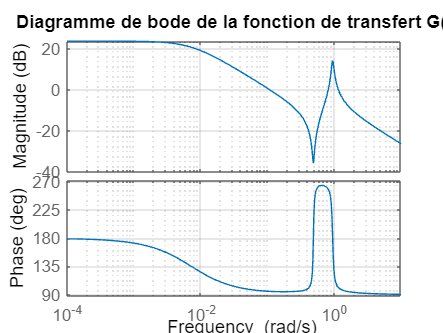

figure, bode(G_s), grid on, title('Diagramme de bode de la fonction de transfert G(s) ')

Question A.1.7

% Valeur du gain statique sur le diagramme de Bode 
% La valeur du gain statique peut etre directement reccuperee en basse
% frequence sur le diagramme de Bode mais elle sera indiquee en dB 

% en BF sur le diagramme de Bode, on est a 180 degre de phase et donc ceci
% indique qu'on a un gain statique negatif. Alors: 
Gain_dB = 23.7; 
Gain_Statique = (-1)*10^(Gain_dB/20)

Gain_Statique = -15.3109

Question A.1.8

% Trace de la reponse du systeme... beta = 1
% [Y,T,X,P] = initial(SYS)
[Y,T] = initial(SYS,[1;0;0;0])

Y =          0
    0.1947
    0.3693
    0.5068
    0.5942
    0.6236
    0.5931
    0.5067
    0.3738
    0.2080


T =          0
    0.3317
    0.6633
    0.9950
    1.3266
    1.6583
    1.9900
    2.3216
    2.6533
    2.9850


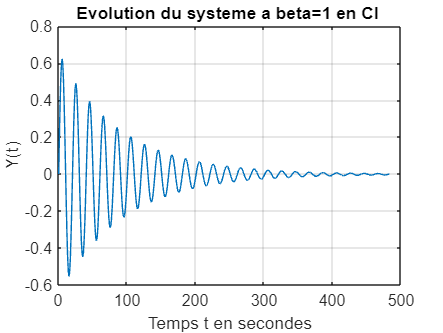

figure, plot(Y), xlabel('Temps t en secondes'), ylabel('Y(t)'),title('Evolution du systeme a beta=1 en CI '), grid on; 

Determination d'une loi de commande classique 

Question A.2.1 & A.2.2 

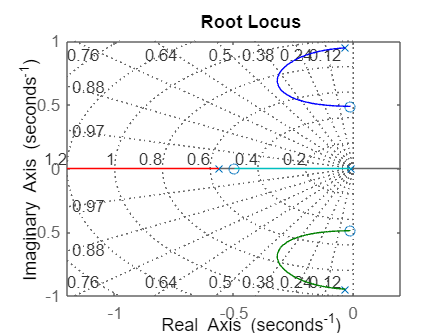

% Utilisons la commande rlocus pour représenter l'évolution de la position des pôles dans le plan complexe

% Valeur maximale du coefficient d'amortissement que l'on peut obtenir avec
% une action proportionnelle
figure, rlocus(-SYS), sgrid; 

Question A.2.3

Question A.2.4

feedback_G_s =
 
    -0.475 s^3 - 0.2479 s^2 - 0.1187 s - 0.05633
  -------------------------------------------------
  s^4 + 0.1608 s^3 + 0.691 s^2 + 0.3929 s - 0.05265
 
Continuous-time transfer function.
Model Properties


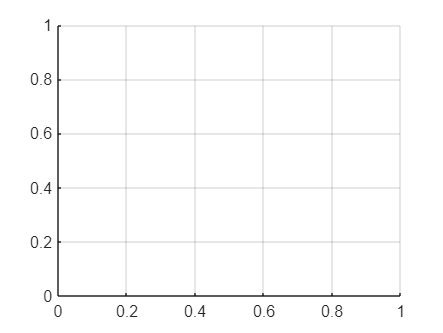

figure, feedback_G_s= feedback(G_s,1), grid on; 

Question A.2.5

% SYS_feedback = tf(feedback_rp) 

% Diagramme de Bode de la FTBF 
FTBF_s = feedback_G_s/(1+feedback_G_s)

FTBF_s =
 
     -0.475 s^7 - 0.3243 s^6 - 0.4868 s^5 - 0.4333 s^4 - 0.1635 s^3 - 0.07251 s^2 - 0.01588 s + 0.002966
  ----------------------------------------------------------------------------------------------------------
  s^8 - 0.1534 s^7 + 1.084 s^6 + 0.5213 s^5 + 0.06519 s^4 + 0.3626 s^3 + 0.009106 s^2 - 0.05726 s + 0.005738
 
Continuous-time transfer function.


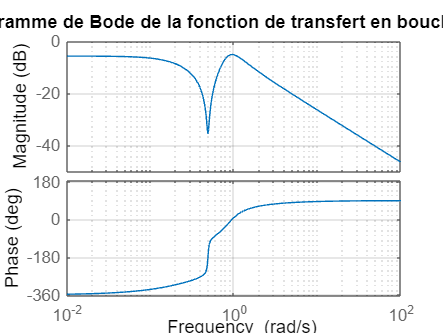

figure, bode(FTBF_s), grid on, title('Diagramme de Bode de la fonction de transfert en boucle fermee ')

Question A.2.6 

% Valeur du gain statique sur le Diagramme de Bode de la FTBF 
% VAleur de la phase egale a -360 degres alors on a bien un signe positif
% sur la valeur du gain 
gain_dB_feeback = -5.741

gain_dB_feeback = -5.7410

gain_feedback = 10^(gain_dB_feeback/20)

gain_feedback = 0.5164

Question A.2.7 & A.2.8

% Nouveau modee de la dynamique de vol 
tau = 3; 
washout_s = tau*s/(1 + tau*s)

washout_s =
 
    3 s
  -------
  3 s + 1
 
Continuous-time transfer function.
Model Properties



gouverne_s = 10/(s +10)

gouverne_s =
 
    10
  ------
  s + 10
 
Continuous-time transfer function.
Model Properties


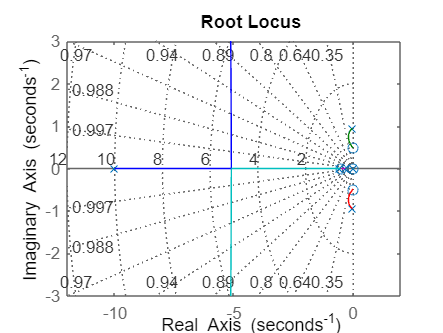

Kgyr = gain_feedback; 

figure, rlocus(-G_s*gouverne_s*washout_s), sgrid;

% Le coefficient maximale que l'on peut obtenir est egal a 2.69


Question A.2.10

% Fonction de transfert en boucle fermee obtenue 
feedback(G_s*gouverne_s*washout_s,Kgyr)

ans =
 
                 -14.25 s^4 - 7.437 s^3 - 3.561 s^2 - 1.69 s
  -------------------------------------------------------------------------
  3 s^6 + 32.91 s^5 + 25.17 s^4 + 33.16 s^3 + 23.42 s^2 + 4.358 s + 0.03674
 
Continuous-time transfer function.
Model Properties


Question A.2.11

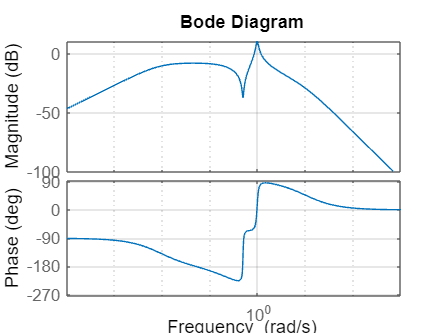

figure, bode(feedback(G_s*gouverne_s*washout_s,Kgyr)), grid on; 

Question A.2.12

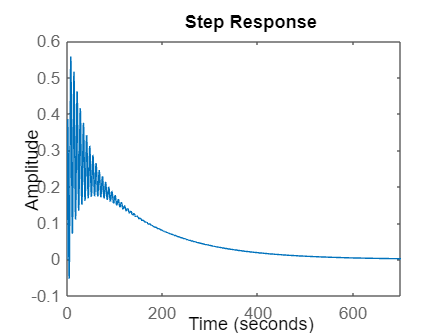

% Reponse du systeme a une condition initiale sur le glissement 
step(-G_s*gouverne_s*washout_s)

Dtermination d'une loi de commande par placement de poles 

Question A.3.1

% Les matrices Ae, Be, ce et De sont obtenues en faisant le calculs qui
% suit dans l'ordre decrit dans le schema fonctionnel
syms rho real 
SYS2 = washout_s*SYS*gouverne_s
Ae = [SYS2.A               zeros(6,6)
     -(SYS2.C)'*SYS2.C    -(SYS2.A)'] 


Be = [SYS2.B
        zeros(6,1)   ]

Ce = [zeros(6,1)'     (SYS2.B)']
De = 0

% Expression de la matrice H 
H = Ae - 1/rho*Be*Ce  

rsqsiso(Ae,Be,Ce,De) ; 

SECTION HELP FUNCTION

help roots 

 roots  Find polynomial roots.
    roots(C) computes the roots of the polynomial whose coefficients
    are the elements of the vector C. If C has N+1 components,
    the polynomial is C(1)*X^N + ... + C(N)*X + C(N+1).
 
    Note:  Leading zeros in C are discarded first.  Then, leading relative
    zeros are removed as well.  That is, if division by the leading
    coefficient results in overflow, all coefficients up to the first
    coefficient where overflow occurred are also discarded.  This process is
    repeated until the leading coefficient is not a relative zero.
 
    Class support for input c: 
       float: double, single
 
    See also poly, residue, fzero.

    Documentation for roots
    

help rlocus

 rlocus  Evans root locus.
 
    rlocus(SYS) computes and plots the root locus of the single-input,
    single-output LTI model SYS. The root locus plot is used to analyze 
    the negative feedback loop
 
                      +-----+
          ---->O----->| SYS |----+---->
              -|      +-----+    |
               |                 |
               |       +---+     |
               +-------| K |<----+
                       +---+
 
    and shows the trajectories of the closed-loop poles when the feedback 
    gain K varies from 0 to Inf.  rlocus automatically generates a set of 
    positive gain values that produce a smooth plot.  
 
    rlocus(SYS,K) uses a user-specified vector K of gain values.
 
    rlocus(SYS1,SYS2,...) draws the root loci of several models SYS1,SYS2,... 
    on a single plot. You can specify a color, line style, and marker for 
    each model, for example:
       rloc

help sgrid 

 sgrid  Generate s-plane grid lines for a root locus or pole-zero map.
    sgrid generates a grid over an existing continuous s-plane root
    locus or pole-zero map.  Lines of constant damping ratio (zeta)
    and natural frequency (Wn) are drawn.
 
    sgrid('new') clears the current axes first and sets HOLD ON.
 
    sgrid(Z,Wn) plots constant damping and frequency lines for the 
    damping ratios in the vector Z and the natural frequencies in the
    vector Wn.
 
    sgrid(Z,Wn,'new') clears the current axes first and sets HOLD ON.
 
    sgrid(AX,...) plots the grid on the Axes or UIAxes with handle AX.
 
    See also rlocus, pzmap, and zgrid.

    Documentation for sgrid
    

help feedback 

 feedback  Feedback connection of two input/output systems. 
 
    M = feedback(M1,M2) computes a closed-loop model M for the feedback loop: 
 
           u --->O---->[ M1 ]----+---> y
                 |               |           y = M * u
                 +-----[ M2 ]<---+
 
    Negative feedback is assumed and the model M maps u to y. To apply 
    positive feedback, use the syntax M = feedback(M1,M2,+1).
 
    M = feedback(M1,M2,FEEDIN,FEEDOUT,SIGN) builds the more general feedback 
    interconnection:
 
                       +------+
           v --------->|      |--------> z
                       |  M1  |
           u --->O---->|      |----+---> y
                 |     +------+    |
                 |                 |
                 +-----[  M2  ]<---+
 
    The vector FEEDIN contains indices into the input vector of M1 and
    specifies which inputs u are involved in the feedback loop. Similarly, 
    FEED

help initial 

 initial  Initial condition response of state-space models.
 
    For SS or SPARSS models, initial computes the unforced response y from
    the initial state XINIT:
 
      Continuous time:  dx/dt = A x,  y = C x,  x(t0) = XINIT
 
      Discrete time:  x[k+1] = A x[k],  y[k] = C x[k],  x[k0] = XINIT.
 
    For LTVSS or LPVSS models, initial computes the response with initial
    state XINIT, initial parameter PINIT (when required), and input held to
    its offset value (u(t)=u0(t) or u(t)=u0(t,p)). This corresponds to the
    initial condition response of the local linear dynamics.
 
    [Y,T] = initial(SYS,XINIT) computes the Y from the initial state XINIT.
    The time vector T is expressed in the time units of SYS and the time
    range and number of points are chosen automatically. Y is of size
    [NUMEL(T) NY] where NY is the number of outputs.
 
    [Y,T] = initial(SYS,XINIT,TFINAL) simulates 